## Derivation of Temperature Profiles

The temperature at the surface was assumed to be given by a sinusoidal function that varies between  and :


$$T\left(t\right)=\frac{T_{\max } +T_{\min } }{2}+\frac{T_{\max } -T_{\min } }{2}\sin \left(\frac{\pi }{12}t\right)\;\;\;\;\;0\le t\le 24$$
 

**Variable Definition**

clear all;
clc;
global aa1 aa2 Tmax Tmin ll1 ll2 H c


$$\begin{array}{l}
H:\mathrm{AC}\;\mathrm{Thickness}\;\left\lbrack m\right\rbrack \\
c\;\;:\mathrm{Initial}\;\mathrm{Temperature}\;\left\lbrack \mathrm{°C}\right\rbrack \\
\mathrm{aa1}\;\;:\mathrm{Thermal}\;\mathrm{Conductivity},\mathrm{AC}\;\mathrm{Layer}\;\left\lbrack \mathrm{Kcal}/hm\mathrm{°C}\right\rbrack \\
\mathrm{aa2}\;\;:\mathrm{Thermal}\;\mathrm{Conductivity},\mathrm{Granular}\;\mathrm{Layer}\;\left\lbrack \mathrm{Kcal}/hm\mathrm{°C}\right\rbrack \\
\mathrm{ll1}\;\;\;:\mathrm{Thermal}\;\mathrm{Diffusivity},\mathrm{AC}\;\mathrm{Layer}\;\left\lbrack \mathrm{m2}/h\right\rbrack \\
\mathrm{ll2}\;\;\;:\mathrm{Thermal}\;\mathrm{Diffusivity},\mathrm{Granular}\;\mathrm{Layer}\;\left\lbrack \mathrm{m2}/h\right\rbrack \\
Z\;\;\;\;\;:\;\mathrm{Abaqus}\;Y\;\mathrm{coordinate}\;\left\lbrack m\right\rbrack 
\end{array}$$


H=0.085;     % Wearing Surface + Binder Layer
Tmax=21.00;  % Starting value
Tmin=15.00;  % Not neccesarily the minimum of the distribution
t=6;   % Shape Factor
c=18;  % Gradient       
aa1=0.0021;
aa2=0.0030;
ll1=1.38;
ll2=1.00;

**Parameters of the 10-point Quadrature Formula**

Reference: (Stroud and Secrest, 1966, p. 308)


$$\frac{1}{2\pi i}\int_{\nu -i\infty }^{\nu -i\infty } \frac{1}{p}\mathrm{V}{\left(p\right)}e^p dp\approx \sum_{j=1}^{10} w_j V\left(p_j \right)$$


Pj=[0.1283767707781087E2 + 1i*0.1666062584162301E1
   0.1283767707781087E2 - 1i*0.1666062584162301E1
   0.1222613148416215E2 + 1i*0.5012719263676864E1
   0.1222613148416215E2 - 1i*0.5012719263676864E1
   0.1093430343060001E2 + 1i*0.8409672996003092E1
   0.1093430343060001E2 - 1i*0.8409672996003092E1
   0.8776434640082609E1 + 1i*0.1192185389830121E2
   0.8776434640082609E1 - 1i*0.1192185389830121E2
   0.5225453367344361E1 + 1i*0.1572952904563926E2
   0.5225453367344361E1 - 1i*0.1572952904563926E2];

Wj=[-0.8684606112670226E3 + 1i*0.1545742053305275E5
   -0.8684606112670226E3 - 1i*0.1545742053305275E5
   0.1551634444257753E4 - 1i*0.8439832902983925E4
   0.1551634444257753E4 + 1i*0.8439832902983925E4
   -0.8586520055271992E3 + 1i*0.2322065401339348E4
   -0.8586520055271992E3 - 1i*0.2322065401339348E4
   0.1863271916070924E3 - 1i*0.2533223820180114E3
   0.1863271916070924E3 + 1i*0.2533223820180114E3
   -0.1034901907062327E2 + 1i*0.4110935881231860E1
   -0.1034901907062327E2 - 1i*0.4110935881231860E1];

**Determining the points to be analized**

% Coordinates of the nodes being considered [m]

% Layer 1
NElem=9; Thick=50; Bias=1.01; 
Zn=[]; Zn(1)=0; Z=[]; Z(1)=0;
Zn(2)=Thick*(power(Bias,1/(NElem-1))-1)/(power(Bias,NElem/(NElem-1))-1);
Z(2)=Zn(2)/1000;
for i=3:NElem+1
    Zn(i)=Zn(i-1)*power(Bias,1/(NElem-1));
    Z(i)=sum(Zn)/1000;
end

% Layer 2
NElem2=8; Thick2=50; Bias2=1.30;  
Zn(NElem+2)=Thick2*(power(Bias2,1/(NElem2-1))-1)/(power(Bias2,NElem2/(NElem2-1))-1);
Z(NElem+2)=Zn(NElem+2)/1000;

for i=NElem+3:NElem+NElem2+1
    Zn(i)=Zn(i-1)*power(Bias2,1/(NElem2-1));
    Z(i)=sum(Zn)/1000;
end



**Solving the Integral**

Int=0;
for tt=1:size(Z,2)
    z=Z(tt);
    for ii=1:10
        p=Pj(ii);
        w=Wj(ii);
        Fj=FFs(p,z,t);
        Int1=w*Fj;
        Int=Int1+Int;
    end
    Temp(tt)=Int;
    Int=0; 
end

TOC=[1000*Z' (Temp+c)'];


**Plot**

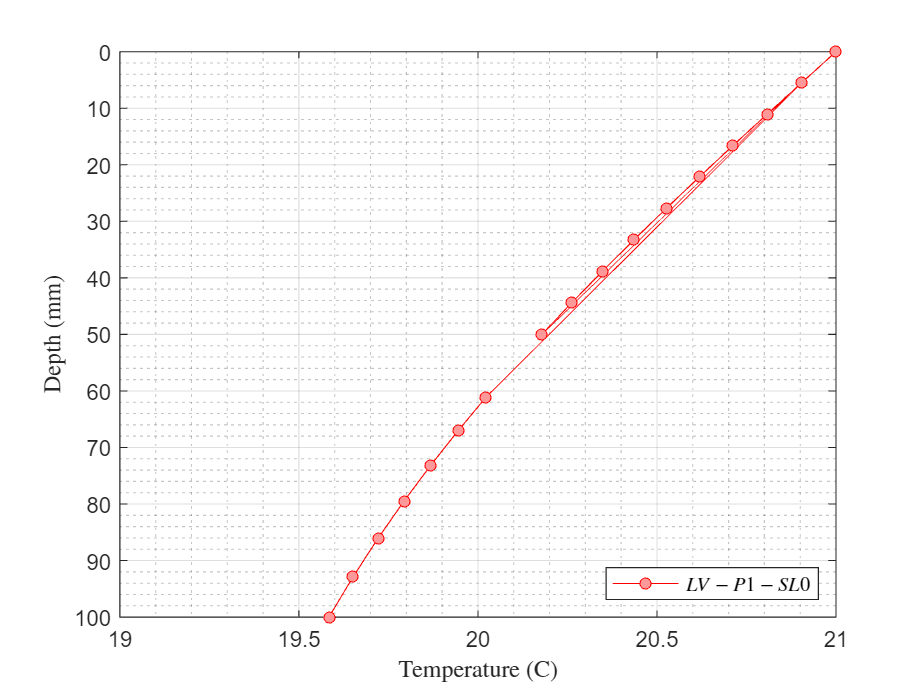

figure;
plot(Temp+c,Z*1000,"-o","color",'r','MarkerSize',5, ...
    'MarkerEdgeColor','red','MarkerFaceColor',[1 .6 .6]);

hold on;
% title('LV_P1_SL0');
xlabel('Temperature (C)','Interpreter','latex');
ylabel('Depth (mm)','Interpreter','latex');
legend('$LV-P1-SL0$','Interpreter','latex','Location','southeast');
xlim([19 21]);
ylim([0,Thick+Thick2]);
set(gca,'YDir','reverse'); % axis(XY)
grid on; grid minor;

**Output Table**

Temp_C=Temp+c;
Z_Esc=Z*1000;

fprintf('Z[mm]  T[C]')

Z[mm]  T[C]

for r=1:length(Z)
    fprintf('%2.2f  %2.2f \n', Z_Esc(r),Temp_C(r));
end

0.00  21.00 
5.53  20.90 
11.06  20.81 
16.60  20.71 
22.15  20.62 
27.71  20.53 
33.27  20.44 
38.84  20.35 
44.42  20.26 
50.00  20.18 
5.46  20.90 
61.13  20.02 
67.02  19.94 
73.13  19.87 
79.47  19.79 
86.06  19.72 
92.90  19.65 
100.00  19.58 
